% Load PGM Files and Compute HOG-based Features
files = dir('./CarData/TrainImages/*.pgm');
num_files = numel(files);

sub_image_size = [20, 20];
num_bins = 8;

X_hog = [];
Y = [];

for i = 1:num_files
    % Load PGM file
    img = imread(fullfile('./CarData/TrainImages', files(i).name));
    
    % Divide the image into non-overlapping sub-images
    sub_images = im2col(img, sub_image_size, 'distinct');
    
    % Compute HOG for each sub-image
    sub_hogs = [];
    for j = 1:size(sub_images, 2)
        sub_image = reshape(sub_images(:, j), sub_image_size);
        sub_hog = extractHOGFeatures(sub_image, 'CellSize', [4 4], 'BlockSize', [1 1], 'NumBins', num_bins);
        sub_hogs = [sub_hogs; sub_hog];
    end
    

    image_hog = reshape(sub_hogs', 1, []);
    
    X_hog(end+1, :) = image_hog;
    
    class_label = files(i).name(1:3);
    if strcmp(class_label, 'neg')
        Y(end+1, 1) = 0;
    elseif strcmp(class_label, 'pos')
        Y(end+1, 1) = 1;
    end
end


rng(0);

num_samples = size(X_hog, 1);
indices = randperm(num_samples);

training_ratio = 2/3;
num_training_samples = round(training_ratio * num_samples);
num_validation_samples = num_samples - num_training_samples;

train_indices = indices(1:num_training_samples);
validation_indices = indices(num_training_samples+1:end);

X_train = X_hog(train_indices, :);
Y_train = Y(train_indices, :);

X_validation = X_hog(validation_indices, :);
Y_validation = Y(validation_indices, :);

% Classification using k-Nearest Neighbors (k-NN) with histogram intersection
k = 5;  % Number of neighbors
predicted_labels = zeros(num_validation_samples, 1);

for i = 1:num_validation_samples
    similarities = sum(min(X_train, X_validation(i, :)), 2);
    [~, sorted_indices] = sort(similarities, 'descend');
    k_indices = sorted_indices(1:k);
    k_labels = Y_train(k_indices);
    predicted_labels(i) = mode(k_labels);
end

accuracy = sum(predicted_labels == Y_validation) / num_validation_samples;
fprintf('Validation Accuracy: %.2f%%\n', accuracy * 100);

Validation Accuracy: 70.29%


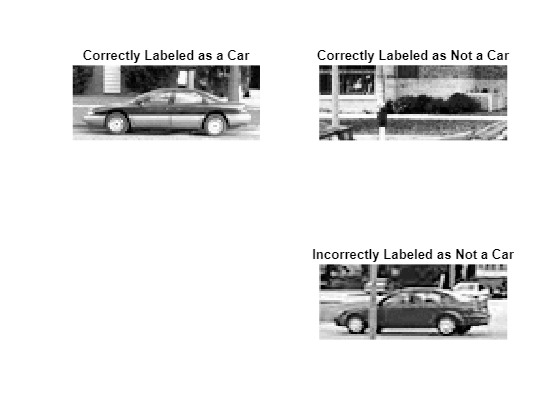


figure;

correct_car_idx = find(predicted_labels == 1 & Y_validation == 1, 1);
correct_not_car_idx = find(predicted_labels == 0 & Y_validation == 0, 1);
incorrect_car_idx = find(predicted_labels == 1 & Y_validation == 0, 1);
incorrect_not_car_idx = find(predicted_labels == 0 & Y_validation == 1, 1);

subplot(2, 2, 1);
imshow(imread(fullfile('./CarData/TrainImages', files(validation_indices(correct_car_idx)).name)));
title('Correctly Labeled as a Car');

subplot(2, 2, 2);
imshow(imread(fullfile('./CarData/TrainImages', files(validation_indices(correct_not_car_idx)).name)));
title('Correctly Labeled as Not a Car');


% subplot(2, 2, 3);
% imshow(imread(fullfile('./CarData/TrainImages', files(validation_indices(incorrect_car_idx)).name)));
% title('Incorrectly Labeled as a Car');

subplot(2, 2, 4);
imshow(imread(fullfile('./CarData/TrainImages', files(validation_indices(incorrect_not_car_idx)).name)));
title('Incorrectly Labeled as Not a Car');